# Statistics

## Initial setup

clc;
clear;
close all;

Set the seed of the random number generator.

rng(3);

Generate a sample of random numbers drawn at random from a population.

% pop = random variable normal distributed, mean 20, std 0.1, 100000 row, 1 column 
pop = random("Normal", 20, 0.1, 100000, 1);
% s = random sample, from pop, 150 counts
s = randsample(pop, 150);

**Population: **the entire set of all possible observations, can be finite or infinite.

**Sample: **a subset randomly extracted from the population, it can be extracted with or without re-insertion.

## Histogram

A histogram provides a quick visual insight into how a data set is distributed. The range of possible values is divided into intervals, or *bins*. Then a bar chart is created, where the height of each bar corresponds to how frequently values in that bin appear in the data.

The width of the bins can be non homogeneous, and the width is determined by the binning's formulas

- Scott's binning

- Struges' binning 

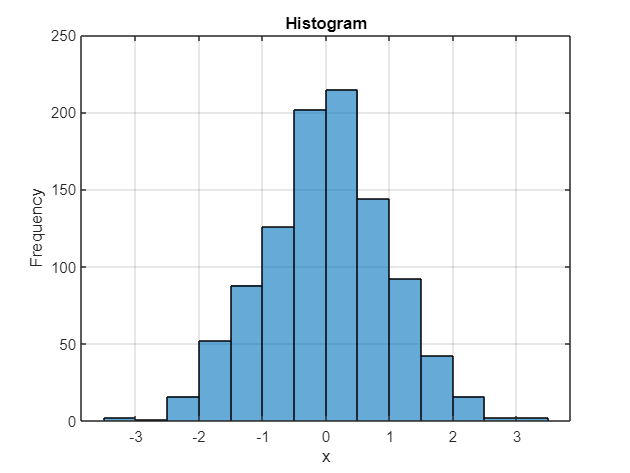

clc;
clear;
close all;

% generete random number with normal distribution
mu = 0; % mean
sigma = 1; % std
r = normrnd(mu,sigma,1000,1); % random variable, mean mu, std sigma, 10000 row, 1 column

% plot the histogram
figure
h = histogram(r,'BinMethod',"sturges"); % function histogram, sample r, bin method struges
grid on
xlabel x
ylabel Frequency
title Histogram

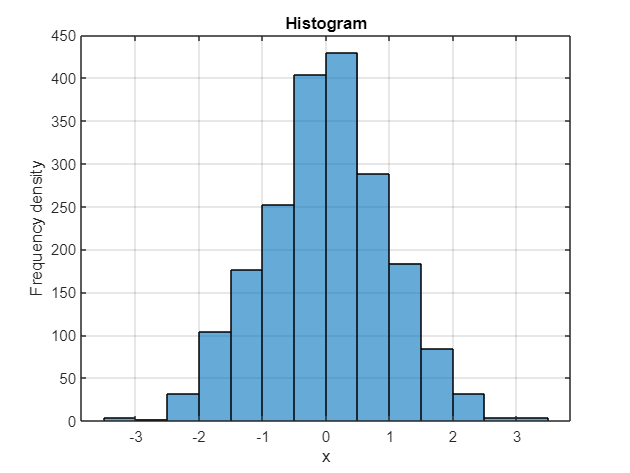

% plot the histogram
figure
histogram(r,'Normalization','countdensity','BinMethod',"sturges");
grid on
xlabel x
ylabel ('Frequency density')
title Histogram

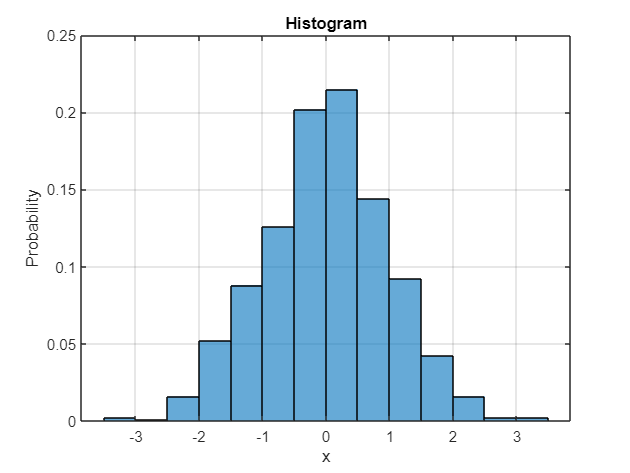

% plot the histogram
figure
histogram(r,'Normalization','probability','BinMethod',"sturges"); % function histogram, sample r, normalization probability,
%                                                                   bin method struges
grid on
xlabel x
ylabel Probability
title Histogram

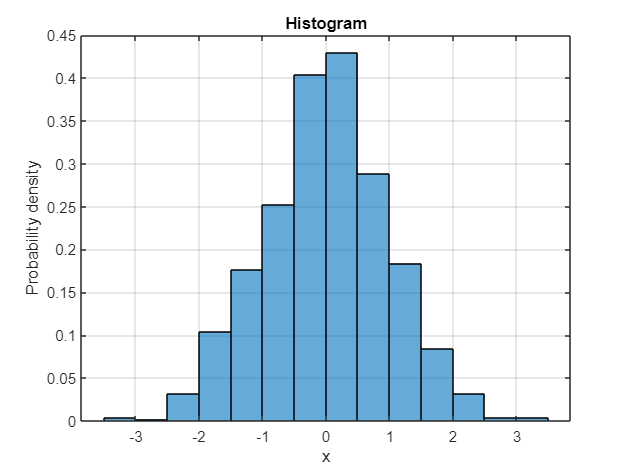

% plot the histogram
figure
histogram(r,'Normalization','pdf','BinMethod',"sturges"); % function histogram, sample r, normalization pdf, bin method struges
grid on
xlabel x
ylabel ('Probability density')
title Histogram

### Cumulated diagram

By accomulating each bar of the histogram from left to right you will get the cumulated diagrams.

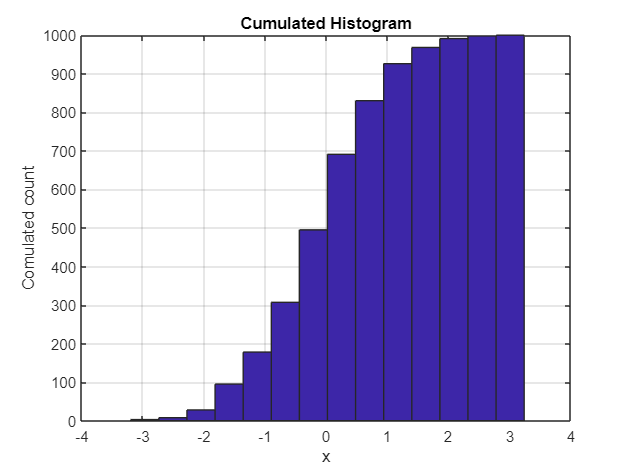

[counts, bins] = histcounts(r,h.NumBins); % uses a number of bins specified by the scalar, nbins
cdfi = cumsum(counts); % returns the cumulative sum of counts starting at the beginning of the first array dimension 
%                        in counts whose size does not equal 1

% plot the cumulative histogram
figure
bar(0.5*(bins(1:end-1)+bins(2:end)),cdfi,'hist');
grid on
xlabel x
ylabel ('Comulated count')
title ('Cumulated Histogram')

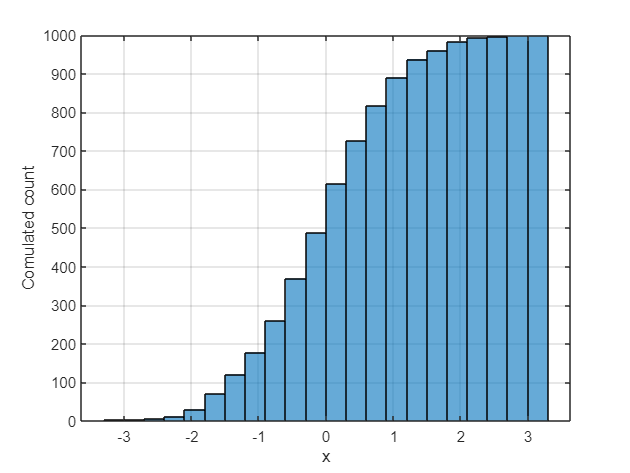

histogram(r, "Normalization","cumcount"); % cumcount = cumulated histogram
xlabel("x");
ylabel("Comulated count");
ylim([0, 1000])
grid();

The cumulative histogram of a population alows you to calculate the probability of finding a value in a given range: $P(a < x < b) = f_{cd}(b) - f_{cd}(a)$

## Central tendency estimators

clc;
clear;
close all;

v = [15 4 12 15 15 13 16 15 12 12 18 20 19 1 30 21 16 16 10 20 20 25 18]; % sample
vS = sort(v); % sorts the elements of v in ascending order.

meanValue = mean(v) % mean value of v

meanValue = 15.7826

medianValue = median(v) % median value of v

medianValue = 16

modeValue = mode(v) % mode value of v

modeValue = 15

## Dispersion estimators

RangeValue = range(v) % range value of v

RangeValue = 29

VarianceValue = var(v) % variance value of v

VarianceValue = 37.8142

StdValue = std(v) % std of v

StdValue = 6.1493

Standard deviation is the square root of variance

### Exercice

We sample a measurement, recording the values of 12.59, 12.26, 12.19, 12.43, 12.90, 12.49. Calculate the standard deviation of the mean, to the 4th significant digit.

q = [12.59 12.26 12.19 12.43 12.90 12.49]; % sample

stdv = std(q); % standard deviation
stdm = std(q)/sqrt(numel(q)); % standard deviation of the mean = std()/sqrt(numel())

## Correlation

clc;
clear;
close all;

mu = 0; % mean
sigma = 1; % std
data = normrnd(mu,sigma,1000,2); % normalized random variable, mean mu, std sigma, 1000 row, 2 column

data(:,2) = data(:,1) + normrnd(2,0.5,size(data,1),1); % define the data(:,2) 

data

data =     0.8706    2.6567
    0.3308    2.0411
   -1.3479    1.1151
    1.5479    3.5506
   -0.6166    1.0661
   -0.6986    1.7306
   -1.4236    0.3360
   -0.1096    2.6352
   -0.1027    1.5826
   -0.3227    1.3803


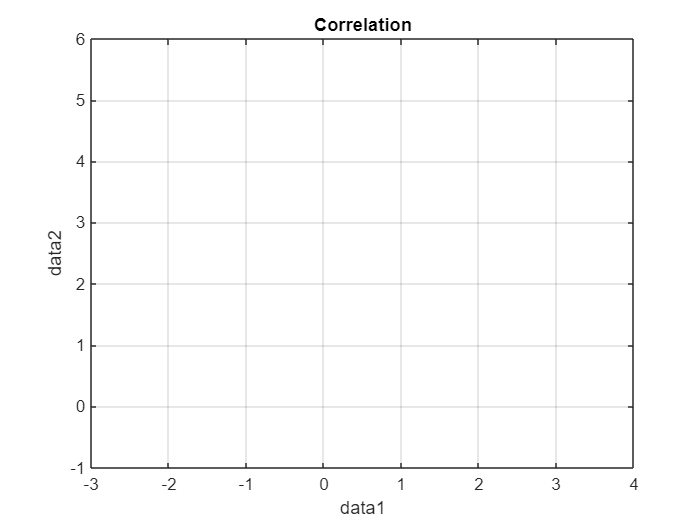


% plot the data
figure
plot(data(:,1), data(:,2), 'o');
title("Correlation");
grid();
xlabel data1
ylabel data2

C = cov(data) % covariance

C =     0.9907    0.9883
    0.9883    1.2404


rho = corr(data) % correlation

rho =     1.0000    0.8915
    0.8915    1.0000


## Reference distribution

Defining reference distributions in mathematical terms allows you to calculate probabilities without knowing the entire population.

You can identify the reference distribution by studying the behaviour of a random sample.

The most common reference distribution are:

- Uniform distribution

- Normal distribution

- chi-sqaure distribution

- Student's T distribution

The distributed function is represented by the *probability density function, *or PDF.

The cululated of the PDF is the cumulated density function. If the $f_{pd}(x)$is the PDF, then the CDF is defined as:

- Lower tail:    $f_{cd,l}(x) = \int_{-\infty}^x f_{pd}(\xi) \mathrm{d}\xi$ 

- Upper tail:    $f_{cd,l}(x) = \int^{\infty}_x f_{pd}(\xi) \mathrm{d}\xi = 1 - f_{cd,u}(x)$

The probability of finding a given value in the range [a,b] is equal to:

#### 
$$P(x \in [a,b]) =  \int^{b}_a f_{pd}(\xi) \mathrm{d}\xi = 

\int^{b}_{-\infty} f_{pd}(\xi) \mathrm{d}\xi - 

\int^{a}_{-\infty} f_{pd}(\xi) \mathrm{d}\xi = f_{cd,l}(a) - f_{cd,l}(b)  $$


#### Example

Given a normal distribution with mean = 25.7 and standard deviation = 1.8, calculate the probability of a value larger than 30

pd = makedist("Normal","mu",25.7,"sigma",1.8) % define a normal distribution (mu = 25.7, sigma = 1.8)

pd =   NormalDistribution

  Normal distribution
       mu = 25.7
    sigma =  1.8


larger30 = 1 - cdf(pd,30) % calculate the probability of a value larger than 30

larger30 = 0.0084

### Uniform distribution

Uniformly distributed data has an equal probability of appearing anywhere in an interval. The pdf is shaped like a rectangle.

The standard uniform distribution is defined as 1/(b - a) on the interval a to b, and 0 everywhere else.

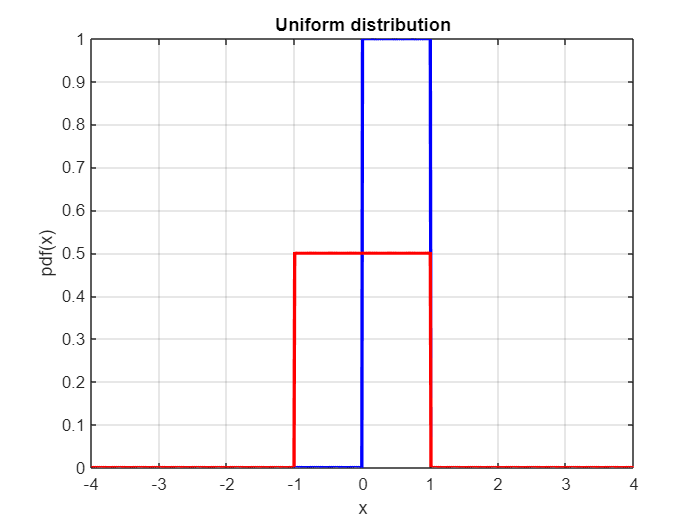

clc;
clear;
close all;

pd1 = makedist('Uniform'); % create an uniform distribution
pd2 = makedist('Uniform','lower', -1, 'upper', 1); % create an uniform distribution defining the extreme

x = -4:0.01:4; % create a vector

pdf1 = pdf(pd1, x); % calculate the probability density function of pd1
pdf2 = pdf(pd2, x); % calculate the probability density function of pd2

% plot the probability density function
figure
plot(x, pdf1, 'b', 'LineWidth', 2);
hold on
plot(x, pdf2, 'r', 'LineWidth', 2);
xlabel("x");
ylabel("pdf(x)");
title("Uniform distribution")
grid();

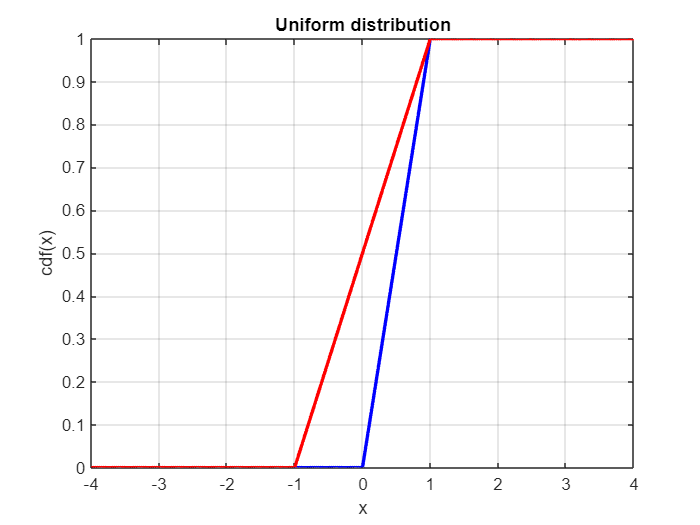

cdf1 = cdf(pd1, x); % calculate the cumulative density function of pd1
cdf2 = cdf(pd2, x); % calculate the cumulative density function of pd2

% plot the cumulative density function
figure
plot(x, cdf1, 'b', 'LineWidth', 2);
hold on
plot(x, cdf2, 'r', 'LineWidth', 2);
xlabel("x");
ylabel("cdf(x)");
title("Uniform distribution")
grid();

### Normal distribution

A normal distribution is the classic "bell curve" distribution. It is defined by the Gauss equation: $f_{pd}(x) =\frac{1}{\sigma \sqrt{2 \pi}}e^{-\frac{1}{2}\left[\frac{x-\mu}{\sigma}\right]^2} $

The most probable values are near the mean, and values further from the mean are less probable.

The normal distribution is defined by two numbers: the mean $\mu$ and the standard deviation $\sigma$. The standard normal distribution has a mean of 0 and standard deviation of 1.

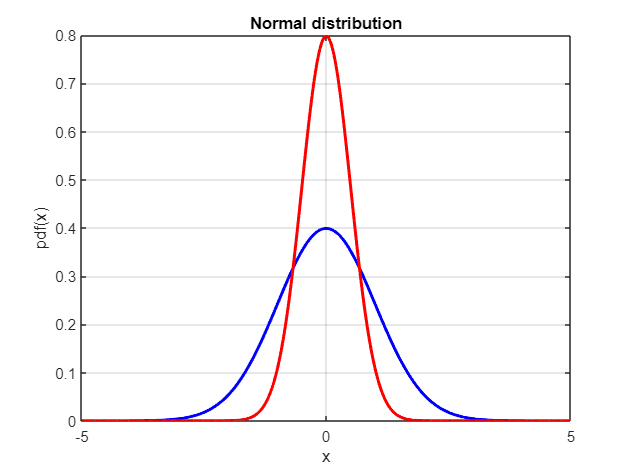

clc;
clear;
close all;

pdN1 = makedist('Normal','mu',0,'sigma',1); % create a normal distribution (mu = 0, sigma = 1)
pdN2 = makedist('Normal','mu',0,'sigma',0.5); % create a normal distribution (mu = 0, sigma = 0.5)

x = -5:0.01:5; % create a vector

pdfN1 = pdf(pdN1, x); % calculate the probability density function of pd1
pdfN2 = pdf(pdN2, x); % calculate the probability density function of pd2

% plot the probability density function
figure
plot(x, pdfN1, 'b', 'LineWidth', 2);
hold on
plot(x, pdfN2, 'r', 'LineWidth', 2);
xlabel("x");
ylabel("pdf(x)");
title("Normal distribution");
grid();

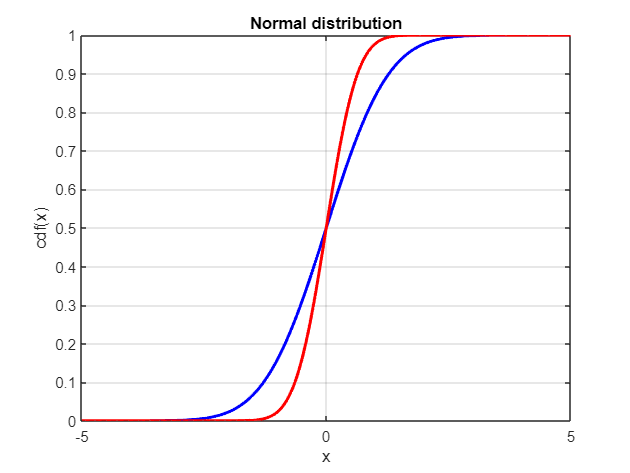

cdfN1 = cdf(pdN1, x); % calculate the cumulative density function of pd1
cdfN2 = cdf(pdN2, x); % calculate the cumulative density function of pd2

% plot the cumulative density function
figure
plot(x, cdfN1, 'b', 'LineWidth', 2);
hold on
plot(x, cdfN2, 'r', 'LineWidth', 2);
xlabel("x");
ylabel("cdf(x)");
title("Normal distribution");
grid();

### Chi-square distribution

It's related to the normal distribution, because it's a sum of a normal distributed variable squared.

It's defined only for positive values because we have the sum of square variables.

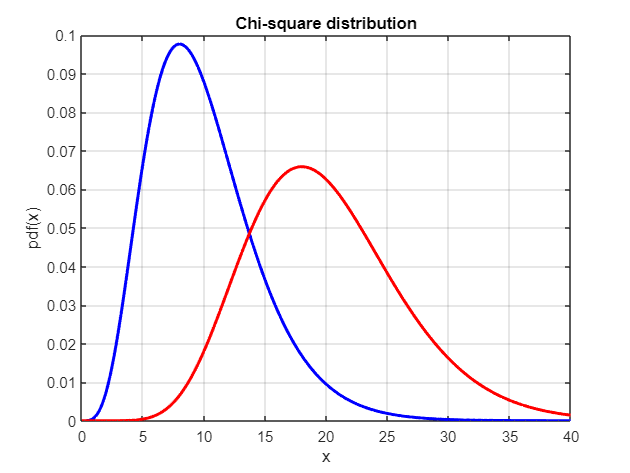

clc;
clear;
close all;

x = 0:0.1:40; % create a vector

% calculate the probability density function of a chi-square distribution of k normal distributed variables
pdfC1 = pdf("Chi-square", x, 10); 
pdfC2 = pdf("Chi-square", x, 20);

% plot the probability density function
plot(x, pdfC1, 'b', "LineWidth",2)
hold on
plot(x, pdfC2, 'r', "LineWidth",2)
xlabel x;
ylabel pdf(x);
title("Chi-square distribution");
grid();
hold off

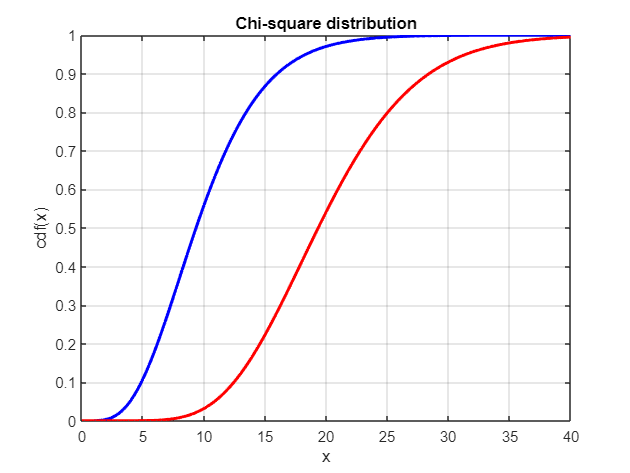

% calculate the cumulative density function of a chi-square distribution of k = 10 normal distributed variables
cdfC1 = cdf("Chi-square", x, 10);
cdfC2 = cdf("Chi-square", x, 20);

% plot the cumulative density function
plot(x, cdfC1, 'b', "LineWidth",2)
hold on
plot(x, cdfC2, 'r', "LineWidth",2)
xlabel x;
ylabel cdf(x);
title("Chi-square distribution");
grid();
hold off

### Student's T distribution

It's a combination of normal distribution and chi square distribution. It is obtained dividing a normal distribution by a chi-sqaure distribution.

The shape is very similar to a normal distribution but the student's T distribution has higher values in the edges and small value in the centre.

For k of about 50 the two distributions are more or less the same.

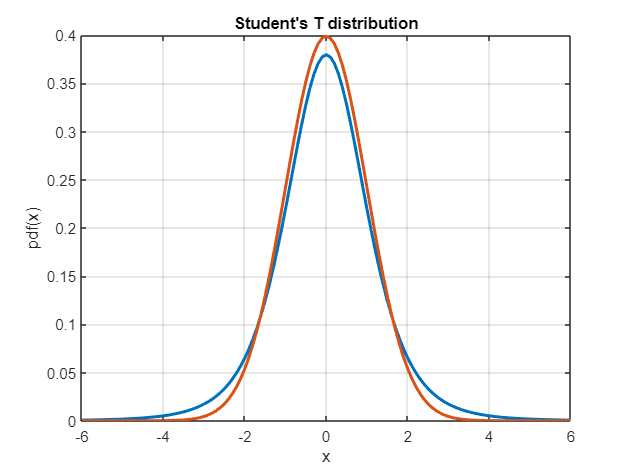

clc;
clear;
close all;

x = -6:0.1:6; % create a vector

% calculate the probability density function of a student's T distribution of k normal distributed variables
pdfT1 = pdf("T", x, 5);
% calculate the probability density function of a normal distribution
pdfT2 = pdf("Normal", x, 0, 1);

% plot the probability density function
plot(x, pdfT1, "LineWidth",2);
hold on
plot(x, pdfT2, "LineWidth",2)
xlabel x;
ylabel pdf(x);
title("Student's T distribution");
grid();
hold off

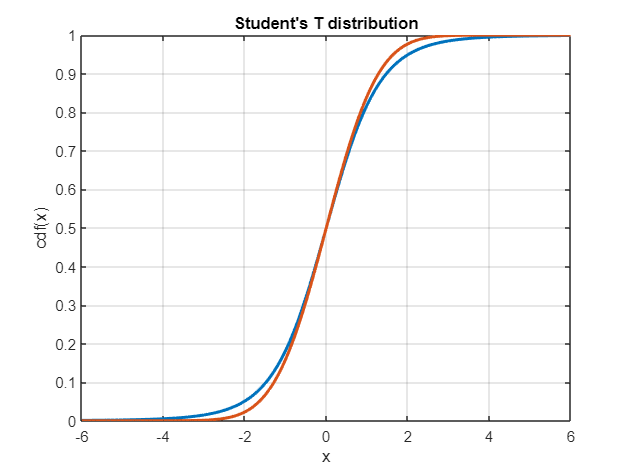

% calculate the cumulative density function of a student's T distribution of k normal distributed variables
cdfT1 = cdf("T", x, 5);
% calculate the cumulative density function of a normal distribution
cdfT2 = cdf("Normal", x, 0, 1);

% plot the cumulative density function
plot(x, cdfT1, "LineWidth",2);
hold on
plot(x, cdfT2, "LineWidth",2)
xlabel x;
ylabel cdf(x);
title("Student's T distribution");
grid(); 
hold off

## Central limit theorem

If $x_1, x_2, ......., x_n$ are *n *indipendent random variables equally distributed, the central limit theorem said that the the sum normalized of the *n *indipendent random variables having the same distribution is a variable that is approximately distributed as $N(0, 1)$.

It is a very robust theorem with respect to hypothesis: for this reason every measurement operation that depends on numerous random factors has a high probability of providing values whose random component is normally distributed.

## Inferential statistics

The inferential statistics is the process for which they induce the characteristics of a population from the observation of a sample extracted at random from the population, a foundamental part of I.S. are the statustical tests.

A statistical test serves to decide which of two opposing hypothesis is more likely to be wrong:

- The null hypothesis $H_0$ is the weak one

- The alternative hypothesis $H_1$ is the strong one

Hypothesis are typically collected in the confusion matrix that relates the truthiness of $H_0$ with the decision outcome.

clc;
clear;
close all;

% plot the confusion matrix
table({'OK';'Type I error'},["Type II error";"OK"],'VariableNames',{'TRUE','FALSE'},'RowNames',{'Accepted','Rejected'})

ans = 2×2 table
                      TRUE               FALSE     
                ________________    _______________

    Accepted    {'OK'          }    "Type II error"
    Rejected    {'Type I error'}    "OK"           


- When null hypothesis is false, accepting it is a type II error

- When null hypothesis is true, rejecting it is a type I error

### T - test

Let's consider a sample *xi*: we standardize the sample mean.


$$t_0=\frac{\bar x - \mu_0}{s / \sqrt{n}} \ \tilde{} \ t_n$$


The result, $t_0$, is distributed as a Student's T with n degrees of freedom. $t_0$ is called test statistic.

Intuitively, $t_0$ is larger when the sample mean is far from the expected value, relatively to its standard decviation.

The smaller the probability of a value larger than $t_0$ on the T distribution, the stronger is the hypothesis that the sample with mean $\bar x$ and variance $\sigma^2$ does not come from a population with expected value $\mu0$.

The probability of a value larger than $t_0$ is called p-value, the p-value is the probability of a type I error.

#### Exercise 1

Calculate the p-value of a one sample, two sides T-test. In Matlab, set the seed of the random number generator to 1 using rng(1), then generate a sample of 10 values normally distributed with mean 10 and standard deviation 0.25.

Check the null hypothesis H0: mu=10.25 and report the p-value.

clc
clear
close all

rng(1) % set the random number generator
sample = random("Normal",10,0.25,10,1); % generate a sample of 10 values normally distributed with mean 10 
%                                         and standard deviation 0.25

[h,p] = ttest(sample,10.25); %  returns:
%                               - a test decision for the null hypothesis that the data in x comes from a normal distribution 
%                                    with mean m and unknown variance.
%                                  -- h = 1 indicates that ttest rejects the null hypothesis at the 5% significance level.
%                                  -- h = 0 indicates that ttest DOES NOT rejects the null hypothesis at the 5% significance level.
%                               - p-value of the test

#### Exercise 2

Calculate the confidence interval for a sample with the following values: 3.46, 3.59, 9.61, 11.34 and return the width of the confidence interval at 95%

xx = [3.46 3.59 9.61 11.34]; % create a vector

[h, p, ci, stats] = ttest(xx); %  returns:
%                               - a test decision for the null hypothesis that the data in x comes from a normal distribution 
%                                 with mean m and unknown variance.
%                                  -- h = 1 indicates that ttest rejects the null hypothesis at the 5% significance level.
%                                  -- h = 0 indicates that ttest DOES NOT rejects the null hypothesis at the 5% significance level.
%                               - p-value of the test
%                               - ci, confidence interval
width = ci(2) - ci(1)

width = 12.9672

#### Exercise 3

Generate two samples taken from normale distributions, exactly in this order and immediatly after setting the seed:

- a sample of 10 elements, with mean 12 and standard deviation 2

- a sample of 12 elements, with mean 13 and standard deviation 2.5

Verify with a Student's T-test that the expected values of the two samples are equal, and provide the p-value for the rest. Assume a confidence level of 95%.

rng(1); % set the random seed

% generete random number with normal distribution

r1 = normrnd(12,2,10,1); % random variable, mean mu, std sigma, 10000 row, 1 column
r2 = normrnd(13,2.5,12,1); % random variable, mean mu, std sigma, 10000 row, 1 column

[h, p] = ttest2(r1, r2)

h = 0

p = 0.1777

[h, p] = ttest(r1)

h = 1

p = 1.1651e-09

[h, p] = ttest(r2)     % returns a test decision for the null hypothesis that the data in vectors x and y comes 

h = 1

p = 1.2457e-08

%                          from independent random samples from normal distributions with equal means and equal 
%                          but unknown variances, using the two-sample t-test.

## Normal analysis

It's used to verify that a sample is compatible with a normal distribution. It is based on the analysis of the sample quantiles and their comparison with the theoretical quantiles of a normal distribution.

### Quantile function

The quantile function is the inverse of the CDF. 

A quantile determines how many values in a distribution are above or below a certain limit

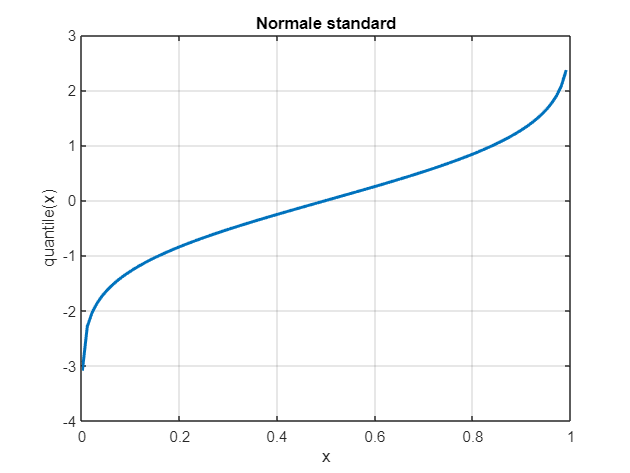

clc;
clear;
close all;

x = 0.001:0.01:9.999; % create a vector


% plot the quantile function: icdf(__)
plot(x, icdf("Normal", x, 0, 1), "LineWidth",2); 
xlabel x;
ylabel quantile(x);
title("Normale standard");
grid();

### Normality plot

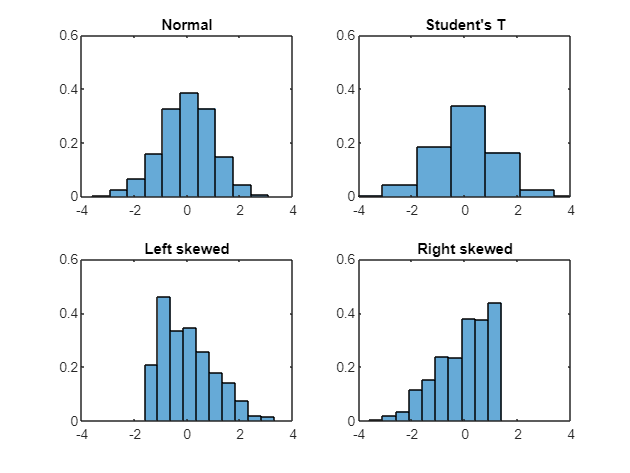

rng(11);

n = 500; % number of count

% define the distributions
x1 = random("Normal", 0, 1, n, 1); % normal distribution
x2 = random("T", 5, n, 1); % Student's T distribution
x3 = pearsrnd(0, 1, 0.8, 3, n, 1); % Left skewed distribution
x4 = pearsrnd(0, 1, -0.8, 3, n, 1); % Right skewed distribution


% plot the distributions
figure
subplot(2, 2, 1);
histogram(x1, 10, "Normalization","pdf");
title("Normal");
axis([-4 4 0 0.6]);

subplot(2, 2, 2);
histogram(x2, 10, "Normalization","pdf");
title("Student's T");
axis([-4 4 0 0.6]);

subplot(2, 2, 3);
histogram(x3, 10, "Normalization","pdf");
title("Left skewed");
axis([-4 4 0 0.6]);

subplot(2, 2, 4);
histogram(x4, 10, "Normalization","pdf");
title("Right skewed");
axis([-4 4 0 0.6]);

The normal plot is the plot of the cumulative probability (quantile) of the sample versus observed value. The ordinate axis is re-scaled according to the CDF of the normal distribution.

A normal sample lines up on the diagonal, non-normal sample show a non linear trend.

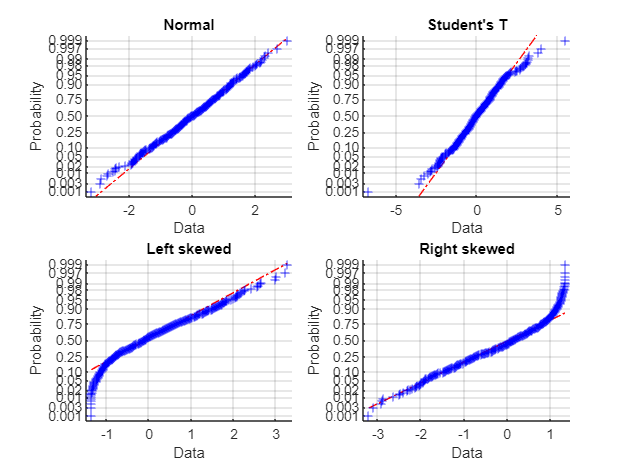

% plot the normal plot

% norplot(x) creates a normal probability plot comparing the distribution of the data in x to the normal distribution.

figure
subplot(2, 2, 1);
normplot(x1);
title("Normal");

subplot(2, 2, 2);
normplot(x2);
title("Student's T");

subplot(2, 2, 3);
normplot(x3);
title("Left skewed");

subplot(2, 2, 4);
normplot(x4);
title("Right skewed");

### Quantile - Quantile plot

It is the plot of the theoretical quantiles of the reference distribution calculated on the cdf of the sample against the sample values.

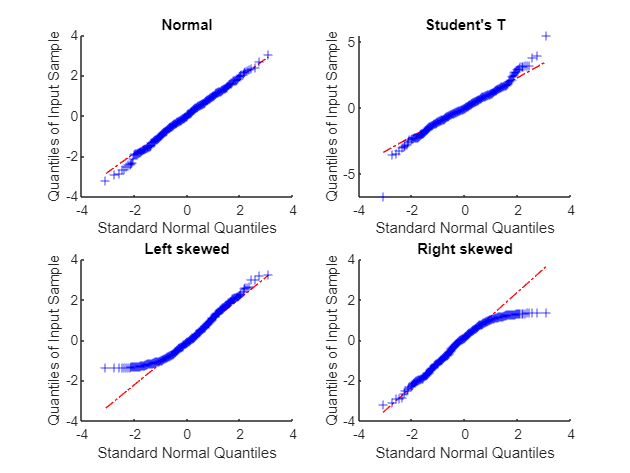

% plot the quantile plot

figure

% qqplot(x) displays a quantile-quantile plot of the quantiles of the sample data x 
% versus the theoretical quantile values from a normal distribution

subplot(2, 2, 1);
qqplot(x1);
title("Normal");

subplot(2, 2, 2);
qqplot(x2);
title("Student's T");

subplot(2, 2, 3);
qqplot(x3);
title("Left skewed");

subplot(2, 2, 4);
qqplot(x4);
title("Right skewed");

You can also plot quantiles of sample A against quantiles of the sample B. In this case you are checking whether the two samples have the same distribution.

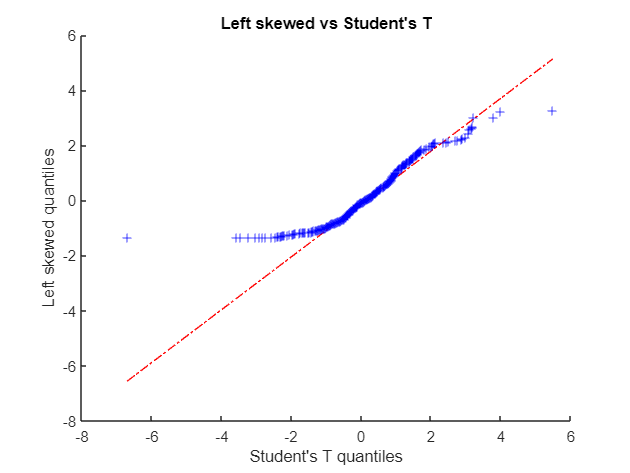

figure
qqplot(x2,x3); % qqplot(x,y) displays a quantile-quantile plot of the quantiles 
%                of the sample data x versus the quantiles of the sample data y
xlabel("Student's T quantiles");
ylabel("Left skewed quantiles");
title("Left skewed vs Student's T");

## Chi-square test

The chi-sqaure test can be used to verify the distribution of a sample, called also *goodness-of-fit.*

Test hypothesis

- $H_0$: the sample is normally distributed

- $H_1$: the sample is NOT normally distributed

Collect sample elements in k bins, each bin large enough to have at least 4-5 observations.

The test statistic is a sum of squared random variables, so it follows the chi-square distribution. This approximation is better the larger is the sample.

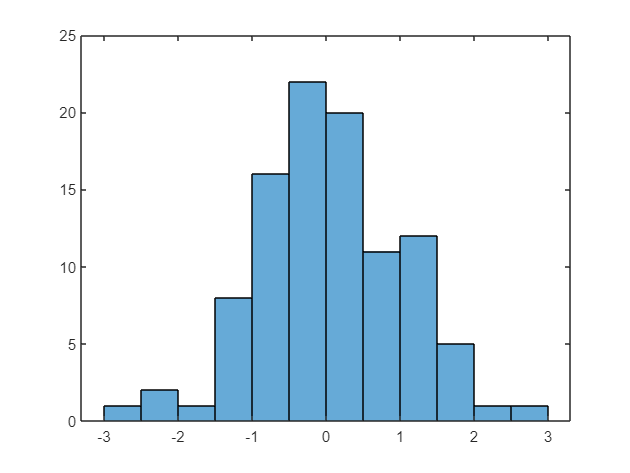

clc;
clear;
close all;

rng(12); % define a random seed

% plot the histogram
x = random("Normal", 0, 1, 100, 1);
figure;
histogram(x);

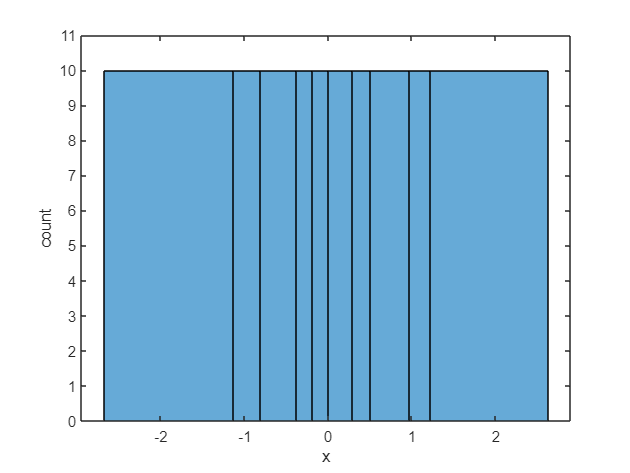

edges = [min(x), quantile(x, 9), max(x)]; % define a list of 11 values that represent the edges

% plot the histogram

histogram(x, edges, "Normalization","count");
ylim([0 11]);
xlabel x;
ylabel count;

[h, p, stats] = chi2gof(x, "Edges", edges) % chi-square test

h = 0

p = 0.2770

stats = struct with fields:
    chi2stat: 8.6725
          df: 7
       edges: [-2.6791 -1.1315 -0.8074 -0.3855 -0.1855 -0.0019 0.2917 0.5087 0.9689 1.2240 2.6305]
           O: [10 10 10 10 10 10 10 10 10 10]
           E: [11.1499 7.6009 13.6847 7.6572 7.3863 11.8927 8.3193 14.6848 5.9354 11.6888]


% return: h = test decision fo the null hyphotesis (h = 0 said that the sample is normal)
%         p = p-value of the hypothesis test (error probability of alternative hypothesis)
%         stats = contatinig information about test statistic
%                   chi2stat — Value of the test statistic.
%                   df — Degrees of freedom of the test.
%                   edges — Vector of bin edges after pooling.
%                   O — Vector of observed counts for each bin.
%                   E — Vector of expected counts for each bin.

### Chi-square exercise

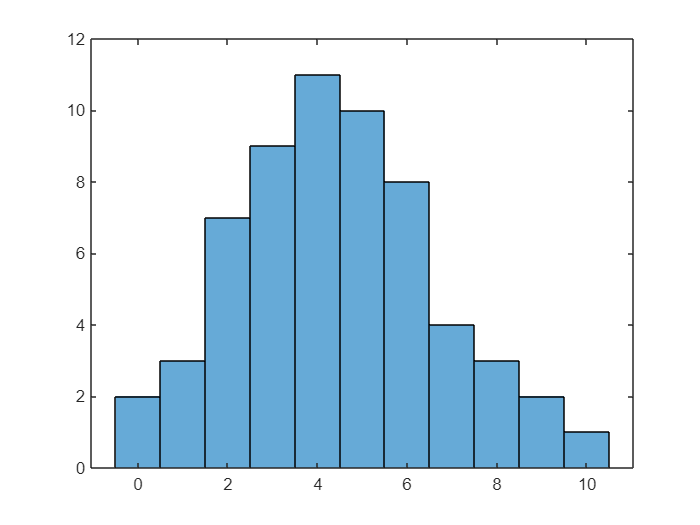

clc;
clear;
close all;

x = [zeros(2,1); ones(3,1); 2*ones(7,1);...
    3*ones(9,1); 4*ones(11,1); 5*ones(10,1);...
    6*ones(8,1); 7*ones(4,1); 8*ones(3,1);...
    9*ones(2,1); 10*ones(1,1);];

nSamples = length(x);

figure
histogram(x);

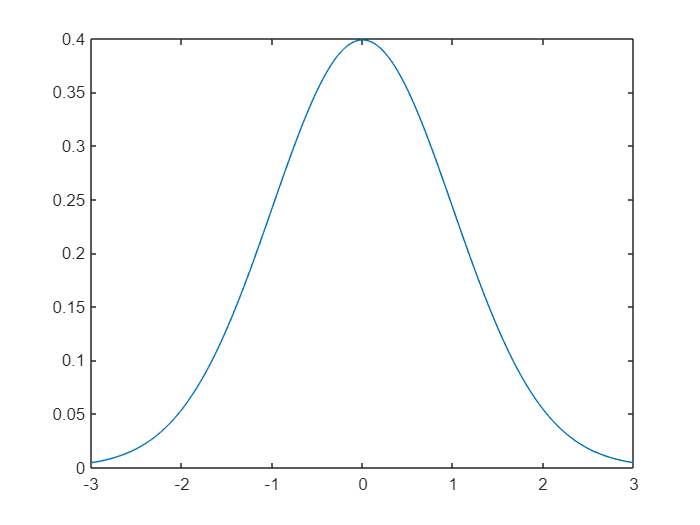

% Estimate meand and variance

mu = mean(x);
sigma = std(x);

% compute the limits of the intervals

edges = min(x)-0.5:max(x)+1;
edges = edges';

% normalize the data

z = (edges - mu)./sigma;

% plot the pdf and cdf of the standard normal distribution

a = -3:0.01:3;
b = normpdf(a,0,1);
figure
plot(a,b);

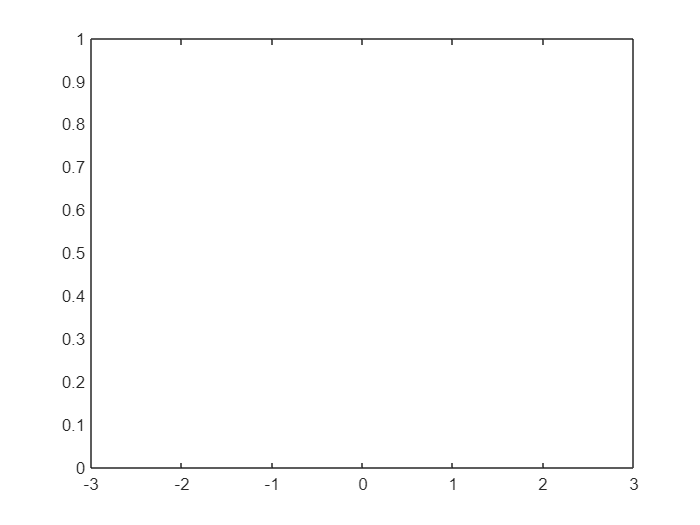

pd = makedist('Normal');
c = cdf(pd, a);
figure
plot(a, c);

fa = zeros(length(z)+1,1);

fa(1) = normcdf(z(1));
fa(end) = 1 - normcdf(z(end));

for ii = 1:length(z)-1
    p = normcdf([z(ii) z(ii+1)]);
    fa(ii+1) = p(2) - p(1);
end

fa = nSamples*fa;

fo = histcounts(x);
fo = fo';

ii = 1;

while sum(fo(1:ii)) < 5
    ii = ii + 1;
end

jj = length(fo);

while sum(fo(end:-1:jj)) < 5
    jj = jj - 1;
end

tmp = [sum(fo(1:ii)); fo(ii+1:jj-1); sum(fo(jj:end))];
tmp2 = [sum(fa(1:ii+1)); fa(ii+2:jj); sum(fa(jj+1:end))];

fo = tmp';
fa = tmp2';

chi_2 = sum(((fa-fo).^2)./fa)

chi_2 = 0.9315

[h,p,st] = chi2gof(x,'Edges',edges') % chi-sqaure test

h = 0

p = 0.9679

st = struct with fields:
    chi2stat: 0.9315
          df: 5
       edges: [-0.5000 1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 10.5000]
           O: [5 7 9 11 10 8 4 6]
           E: [5.7263 5.9329 8.6591 10.3931 10.2585 8.3270 5.5585 5.1446]


## Contingency test

The contingency test verify wether the two classification criteria are statistically independent.

clc;
clear;
close all;

% plot the contingency table
x = table([160;40],[140;60],[40;60],'VariableNames',{'Plan1','Plan2','Plan3'},'RowNames',{'Salary','Hourly'})

x = 2×3 table
              Plan1    Plan2    Plan3
              _____    _____    _____

    Salary     160      140      40  
    Hourly      40       60      60  


data = x{:,:};

n = sum(sum(data)); % number of value

u = sum(data,2)./n; % row vector conataining the sum of each column
v = sum(data)./n; % column vector containing the sum of each raw

e = n.*v.*u; % expected value

chi2 = sum(sum((data-e).*(data-e)./e)); % chi-square value of the test statistic

dof = (size(data,1)-1)*(size(data,2)-1); % degrees of freedom of the test statistic

p = 1-chi2cdf(chi2,dof) % p-value

p = 1.6691e-11

## Outliers

An outlier is an observation that is not compatible with the distribution of the rest of the sample. It may result from an error in conducting the measurement or in transcribing / recording the measured value.

The outliers must be eliminated from the samples, reducing the variance with respect to the expected value. There are two main techniques for detecting outliers:

- Chauvenet's criterion =

- find the mazimum absolute residual: $r_0$

- calculate the probability of a value larger than: $r_0$ on the standard normal: $P(r_0)$

- if the number of expected observation $n* P(r_0)$ is smaller than 0.5 = eliminate it

- Grubb's test = test statistic

Do not apply any criterion twice (or more)!

## Regression analysis

Aim: to identify the parameters of a model that better adapt the model to a set of observations. The model is of type $y = f(x)$, where y is the response or yeld and x is the predictor.

The simplest relationship (and the one you can usually assume as a starting point) is that of a straight line, or $y = a x + b$.

The process of determining *a* and *b* for a set of *x* and *y* data is called *linear regression*.

Aim: to identify the coefficients of the model that minimize a certain performance index, which describes the average distance between the observations and the model. 

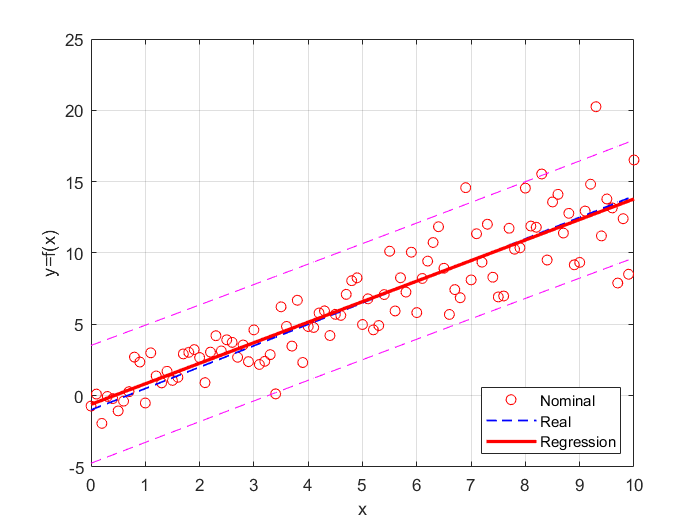

clc;
clear;
close all;

rng default

x = 0:0.1:10;
a = 1.5;
b = -1;
y = a*x + b; % define the model
n = random("Normal", 0, 0.5, [1, numel(x)]).*(x/2 + 1); % create noise
yn = y + n; % add noise at model

[pl, S] = polyfit(x, yn, 1); % returns the coefficients for a polynomial p(x) of degree n that is a best fit 
%                              (in a least-squares sense) for the data in y.
[yf, delta] = polyval(pl, x, S); % returns:
%                                 - evaluates the polynomial p at each point in x
%                                 - delta is an estimate of the standard error in predicting a future observation at x by p(x)

figure
plot(x, yn, "or")
hold on
plot(x, y,'b--', "LineWidth", 1);
plot(x, yf,'r-', "LineWidth", 2);
plot(x,yf+2*delta,'m--',x,yf-2*delta,'m--')
xlabel x;
ylabel y=f(x);
grid
legend(["Nominal", "Real", "Regression"], "Location", "SouthEast")
hold off

mdl = fitlm(x', yn', "linear") % returns a linear regression model of the responses y, fit to the data x.

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.60736     0.40004    -1.5182       0.13214
    x1               1.4396    0.069117     20.828    5.8171e-38


Number of observations: 101, Error degrees of freedom: 99
Root Mean Squared Error: 2.03
R-squared: 0.814,  Adjusted R-Squared: 0.812
F-statistic vs. constant model: 434, p-value = 5.82e-38

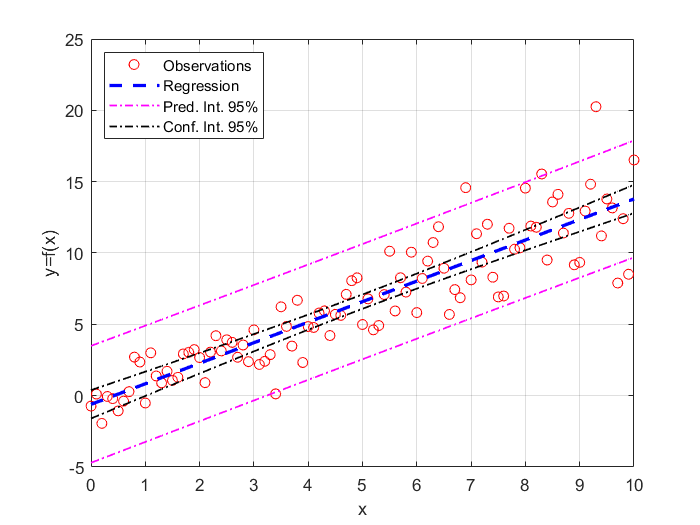

[yhat,ci] = predict(mdl,x','Alpha',0.05, "Simultaneous", true,"Prediction","curve"); % rerurns evaluates the polynomial p at each 
%                                                                                      point in x and the prediction interval
[~,cp] = predict(mdl,x','Alpha',0.05,"Prediction","observation"); % rerurns evaluates the polynomial p at each point in x and the
%                                                                   confidance interval
figure
plot(x, yn, "or")
hold on
plot(x, yhat,'--b', "LineWidth", 2)
plot(x, cp(:,1), "-.m", "LineWidth", 1)
plot(x, ci(:,1), "-.k", "LineWidth", 1)
plot(x, cp(:,2), "-.m", "LineWidth", 1)
plot(x, ci(:,2), "-.k", "LineWidth", 1)
xlabel x
ylabel y=f(x)
legend(["Observations", "Regression", "Pred. Int. 95%", "Conf. Int. 95%"], ...
"Location","northwest")
grid
hold off

The regression model shall be provided with prediction and confidance intervals:

- The prediction interval predicts where a future observation will fall, with a given probability

- The confidence interval defines a range where the expected model has a given probability to be

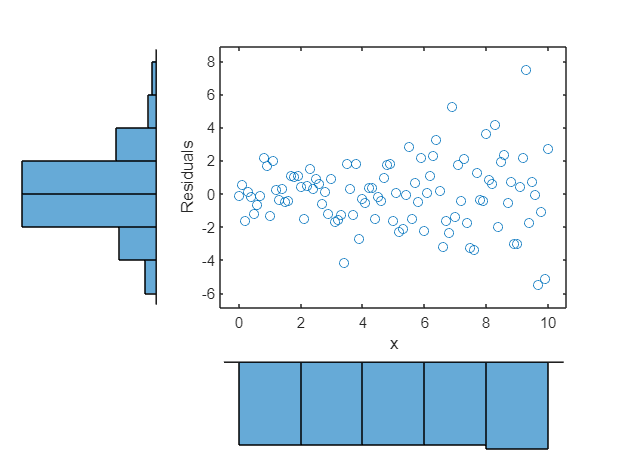

figure
scatterhist(x,mdl.Residuals.Raw, "Direction","out","Location","SouthWest")
xlabel x
ylabel Residuals

[a, pval] = chi2gof(mdl.Residuals.Raw)

a = 0

pval = 0.4063

Regression parameters a,b can also be calculated with matrix calculus $y = (A^T\cdot A)^{-1}\cdot A^T\cdot b$

A=[x',ones(numel(x),1)];
(A'*A)\A'*yf' % nota: A\b is equivalent, but faster and more precise with respect to inv(A)*b

ans =     1.4396
   -0.6074


If the model is suitable for the real phenomenon, then the residuals are random, with no patterns, and normally distributed (to be checked with chi-square test)

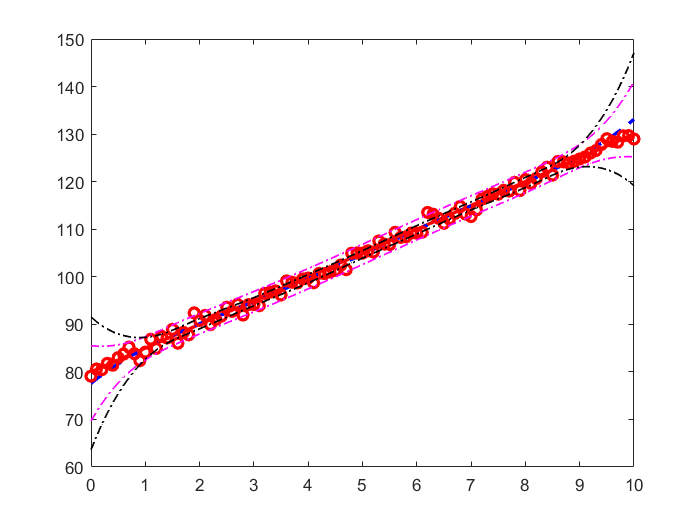

clc;
clear;
close all;

x = 0:0.1:10;
a = 0;
b = 5;
c = 80;

y = a*x.^2 + b*x + c;

yn = y + random("Normal", 0, 1, 1, numel(x));

xl = x(x >= 1 & x <= 9);
yl = yn(x >= 1 & x <= 9);

mdl1 = fitlm(xl, yl, "poly5");
[yhat, ci] = predict(mdl1, x', 'Simultaneous', true, "Prediction","Curve");
[~,cp] = predict(mdl1,x','Alpha',0.05,"Prediction","observation");

figure
plot(x,y,"-r","LineWidth",2)
hold on
plot(x, yhat', "--b","LineWidth",2)
plot(x, yn', "or","LineWidth",2)
plot(x, cp(:,1), "-.m", "LineWidth", 1)
plot(x, ci(:,1), "-.k", "LineWidth", 1)
plot(x, cp(:,2), "-.m", "LineWidth", 1)
plot(x, ci(:,2), "-.k", "LineWidth", 1)

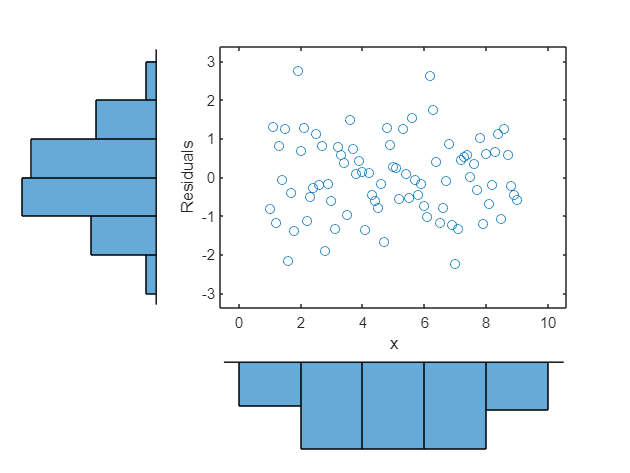

figure
scatterhist(xl,mdl1.Residuals.Raw, "Direction","out","Location","SouthWest")
xlabel x
ylabel Residuals

[a, pval] = chi2gof(mdl1.Residuals.Raw)

a = 0

pval = 0.9997

**Under-fitting: **Residuals that show patterns or that are not normal are symptoms of underfitting

**Over-fitting: **if the model degree is to large, it quickly diverges outside of the fitting range and oscillates following individual observation inside the range

## Static calibration

The calibration of a measuring instrument is the identification of the correlation between the measurand and the output of the instrument itself. During static calibration assuming that neither the measurand nor the output of the instrument are functions of time.

The correlation $y = f(x)$ between input $m$ and output $y$ in static conditions is called static characteristic of the instrument. From the static characteristics and the observed output $y_0$, one gets an estimate of the measurand $m_0$*.*

During calibration, the static characteristic is unknown and a set of known values of the measurand $m_i$, for which the expected output $y_i$ are known, are used for identifying the static characteristic. Known values $m_i$ can be:

- Reference samples for the measurand under study

- Samples or generic input values measured with a reference instrument

In both cases, reference samples and calibration instrument must have been calibrated with an accuracy at least one order of magnitude better than the target one.

Aim of the calibration is to identify the static characteristic and the uncertainty of the measurement instrument.

The **static characteristic** is defined by:

- Developing a model of the instrument

- Collecting calibration data

- Performing regression 

- Validate the regression by analysis of residuals

The **uncertainty** is determined by its components:

- Model uncertainty

- Uncertainty of the estimate of the measurand

- Uncertainty on the calibration curve

The model of the instrument represents the relationship between input and output. A complete model also include the relationship between disturbance inputs and output. The difference between model and reality is called model uncertainty.

A measurement is subject to two types of disturbance inputs:

- **Modifying inputs**: inpacts on the model - to limit this problem, the test sequence is randomize

- **Interfering inputs**: random disturbances that sum to the model output - the dominant disturbances must be controlled while letting free the disturbances that have limited effects, this is called statical control of the measurement process. It is the condition where the central limit theorem applies.

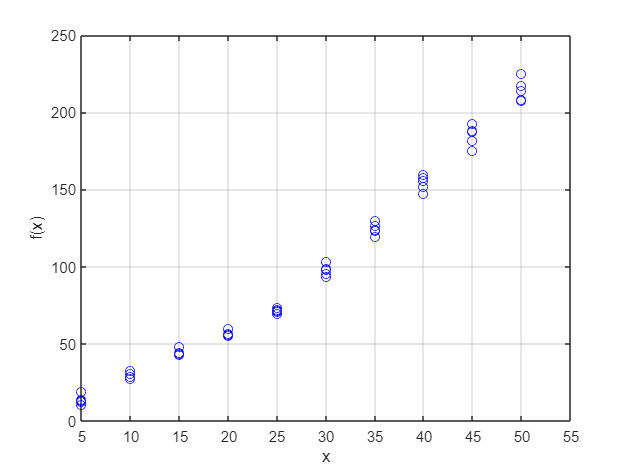

clc;
clear;
close all;

rng(10)

tbl = table();
rep = 5;
n = 10;
noise = 3;
a = 2.9;
b = 0.01;
[i, r] = meshgrid(1:n, 1:rep);

tbl.r = r(:); % repetition
tbl.i = i(:); % measurand index
tbl.t = ((1:numel(tbl.i))/rep')'; % time
tbl.T = max(20, tbl.t*3+5); % temperature
tbl.x = tbl.i * 5; % measurand value
tbl.yn = a * tbl.x + b; % nominal measure
tbl.yT = (tbl.T - 20)*5; % contribute of the temperature (Unknow)
tbl.ryT = tbl.yT(randperm(numel(tbl.i))); % contribute of the temperature randomized
tbl.n = random("Normal", 0, noise, numel(tbl.x),1); % disturbances
tbl.y = tbl.yn + tbl.n + tbl.yT; % measure in sequential order
tbl.ry = tbl.yn + tbl.n + tbl.ryT; % measure in random order

figure
plot(tbl.x, tbl.y, 'ob');
xlabel x
ylabel f(x)
xlim([5 55]);
grid;

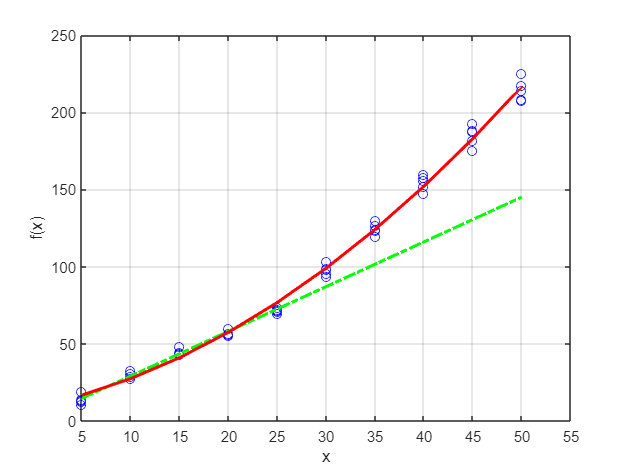

mdl = fitlm(tbl.x, tbl.y, "quadratic");
[tbl.yhat, tbl.ci] = predict(mdl, tbl.x, 'Alpha', 0.05, "Simultaneous", true, "Prediction","curve");

figure
plot(tbl.x, tbl.y, 'ob');
hold on
rl = refline(a, b);
rl.LineWidth = 2;
rl.LineStyle = "-.";
rl.Color = "Green";
plot(tbl.x, tbl.yhat, "-r", "Linewidth",2);
hold off
xlabel x
ylabel f(x)
xlim([5 55]);
grid;

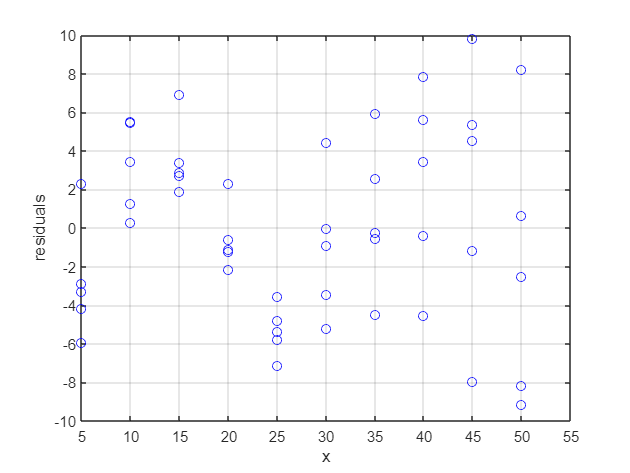

% check the residuals
figure
plot(tbl.x, mdl.Residuals.Raw,'ob');
xlabel x
ylabel residuals
xlim([5 55]);
grid;

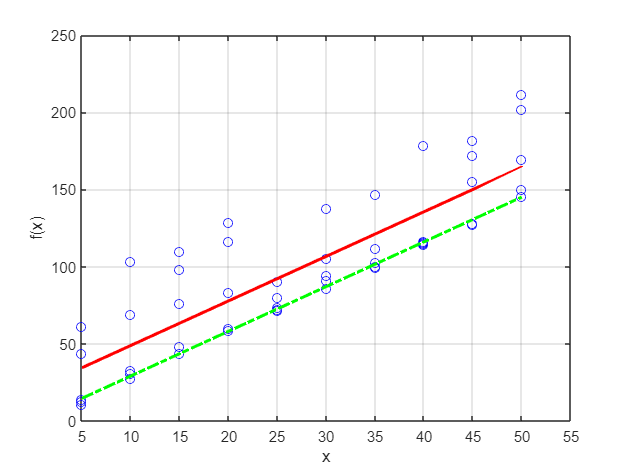

%Randomize sequence
mdlr = fitlm(tbl.x, tbl.ry, "linear");
[tbl.ryhat, tbl.rci] = predict(mdlr, tbl.x, 'Alpha', 0.01, "Simultaneous", true, "Prediction","curve");

figure
plot(tbl.x, tbl.ry, 'ob');
hold on
rl = refline(a, b);
rl.LineWidth = 2;
rl.LineStyle = "-.";
rl.Color = "Green";
plot(tbl.x, tbl.ryhat, "-r", "Linewidth",2);
hold off
xlabel x
ylabel f(x)
xlim([5 55]);
grid;

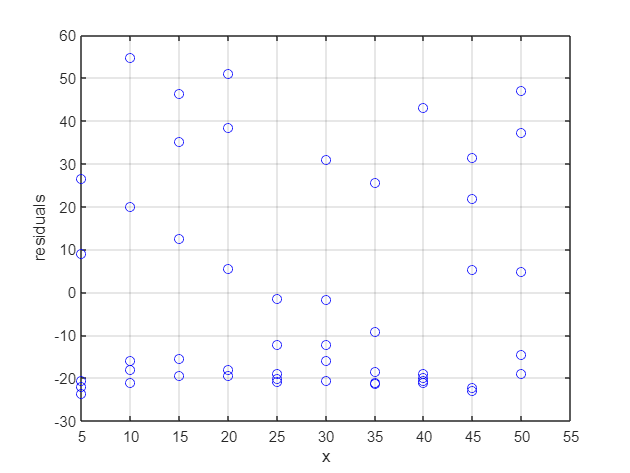

% check the residuals
figure
plot(tbl.x, mdlr.Residuals.Raw,'ob');
xlabel x
ylabel residuals
xlim([5 55]);
grid;

Always randomize the sequence of measurement in any experimental campaign, this allows to transform modyfing disturbances into interfering ones.

## Uncertainty analysis

According to UNI4546 a measurement is a triplet of:

- Value

- Uncertainty

- Measurement unit

It represents a parameter of a system considered in a given state.

Uncertainty has been clearly and precisly defined in the GUN:

- Defines the procedures that guide an operator to define the measurement uncertainty

- Replace error with uncertainty and true value with estimate

Uncertainty only refer to the random, non predictable part of a measurement, possible systematic deviations of the measurement must be corrected beforehand

- **Standard uncertainty**: is defined as the standard deviation of the mean vlaue: $u_x = \frac{\sigma_x}{\sqrt{n}}$

- **Relative uncertainty:** is defined as standard uncertainty in relation to the average of the measurement value: $u_x,rel = \frac{u_x}{\left|{\bar x}\right|}$

It is useful to express the uncertainty as an interval within which the expected value of the population from which the sample of observed measurement values is extracted is likely to fall. The range is said confidence interval, the associated probability is said confidence level.

**Confidence interval**

Recall the Student's T test:


$$t_0=\frac{\bar x - \mu_0}{s / \sqrt{n}} \ \tilde{} \ t_n$$


Given the distribution of $t_0$ is known, we can say tha, by definition:


$$p(-t_{n,\alpha/2}< \frac{\left| \bar x \right| - \mu_0}{s_x / \sqrt{n}} < t_{n,\alpha/2}) = 1 - \alpha $$


Upon rearranging and substituting $u_x = \frac{s_x}{\sqrt{n}}$:


$$p(\bar x-t_{n,\alpha/2}< \mu_0 <\bar x + t_{n,\alpha/2}) = 1 - \alpha $$


Thus the interval $\bar x \pm t_{n,\alpha/2}$ contains the expected value with a confidence level of

### Coverage factor

We define $U_x = k_n \ u_x$ as the extended uncertainty, and $k_n $ coverage factor. The coverage factor is calculated as:

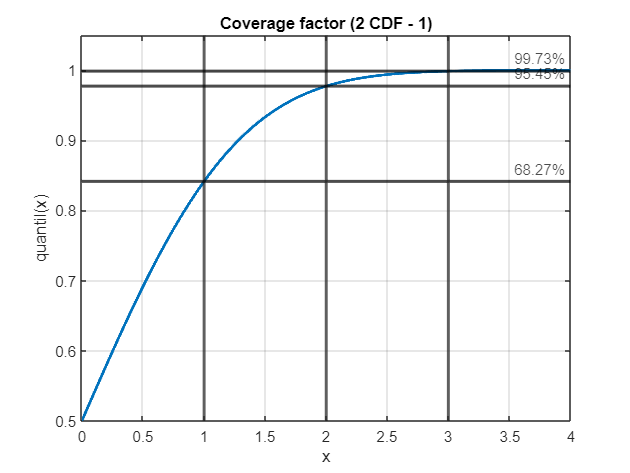

x = 0:0.001:4;
plot(x, cdf("Normal", x, 0, 1), "LineWidth", 2)
xlabel x
ylabel quantil(x)
title("Coverage factor (2 CDF - 1)")
ylim([0.5 1.05]);
grid();
xline(1, "LineWidth", 2);
yline(cdf("Normal", 1, 0, 1), "k", round((2*cdf("Normal", 1, 0, 1)-1) * 100, 2) + "%", "LineWidth", 2);
xline(2, "LineWidth", 2);
yline(cdf("Normal", 2, 0, 1), "k", round((2*cdf("Normal", 2, 0, 1)-1) * 100, 2) + "%", "LineWidth", 2);
xline(3, "LineWidth", 2);
yline(cdf("Normal", 3, 0, 1), "k", round((2*cdf("Normal", 3, 0, 1)-1) * 100, 2) + "%", "LineWidth", 2);

### Rapresentation of the measurement

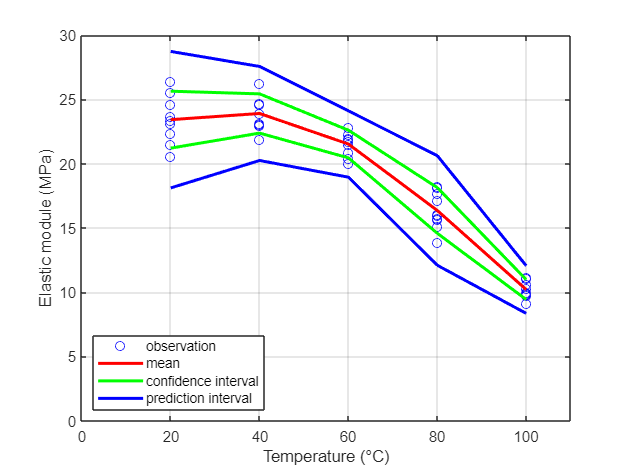

rng default
tbl = table();
rep = 10;
n = 5;
x = 20:20:100;
[i, r] = meshgrid(1:n, 1:rep);
tbl.r = r(:);                      % ripetizione
tbl.i = i(:);                      % indice del misurando
tbl.x = (repelem(x, rep))';
tbl.y = (2000 +20 * tbl.x - 0.3*tbl.x.^2)/100 + (random("Normal", 0, 1, 1, numel(tbl.x)))';
tbl.ci=zeros(numel(tbl.x),1);
tbl.pi=zeros(numel(tbl.x),1);
t = abs(icdf("t", (1-0.9973)/2, rep));
for i = 1:n
    tbl.m(tbl.i == i) = mean(tbl.y(tbl.i == i));
    tbl.pi(tbl.i == i) = 3 * std(tbl.y(tbl.i==i)); % predizione
    tbl.ci(tbl.i == i) = t * std(tbl.y(tbl.i==i))/sqrt(rep); % confidenza
end
plot(tbl.x, tbl.y, "ob")
hold on
plot(tbl.x(tbl.r==1), tbl.m(tbl.r==1), "-r", "LineWidth", 2)
plot(tbl.x(tbl.r==1), tbl.m(tbl.r==1)+tbl.ci(tbl.r==1), "-g", "LineWidth", 2)
plot(tbl.x(tbl.r==1), tbl.m(tbl.r==1)+tbl.pi(tbl.r==1), "-b", "LineWidth", 2)
plot(tbl.x(tbl.r==1), tbl.m(tbl.r==1)-tbl.ci(tbl.r==1), "-g", "LineWidth", 2)
plot(tbl.x(tbl.r==1), tbl.m(tbl.r==1)-tbl.pi(tbl.r==1), "-b", "LineWidth", 2)
hold off
xlim([0 110]);
ylim([0 30]);
legend({'observation', 'mean', 'confidence interval', 'prediction interval'}, "Location","southwest")
xlabel("Temperature (°C)")
ylabel("Elastic module (MPa)")
grid()

### Monte Carlo method

When the relationship between dependent quantity and its component is not analytical and differentiable, but the distributions of the latter are known, it is possible to calculate the combined standard uncertainty using the Mnte Carlo method.

Its an empirical method that involves simulating a large number of combinations of inputs to build the histogram of the dependent variable.

#### Example 1 (pi)

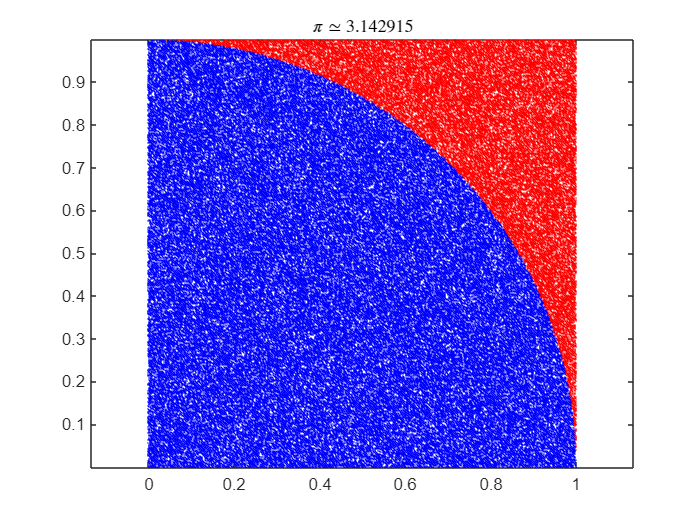

rng default
N =100;
tbl = table();
tbl.x = random("Uniform", 0, 1, 1, N); % r = 1
tbl.y = random("Uniform", 0, 1, 1, N);
tbl.in = sqrt(tbl.x.^2+tbl.y.^2) <= 1;
pi_approx = numel(tbl.x(tbl.in))/N*4;
plot(tbl.x(~tbl.in), tbl.y(~tbl.in), ".r", "MarkerSize",1)
title(sprintf("$\\pi\\simeq$%f", pi_approx), "Interpreter","latex");
axis equal
hold on
plot(tbl.x(tbl.in), tbl.y(tbl.in), ".b", "MarkerSize",1)
hold off

#### Example 2 (volume of a cylinder)

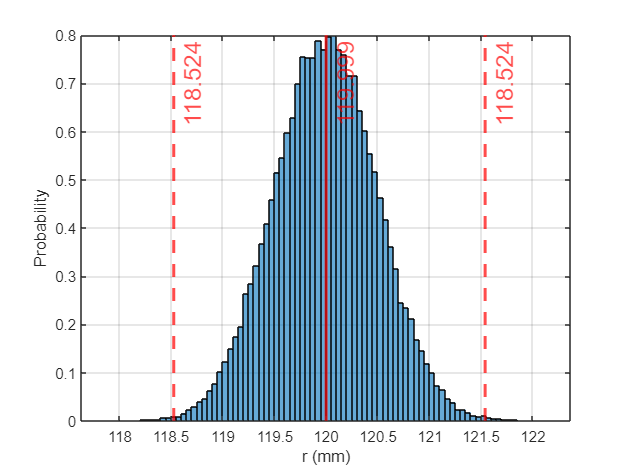

clc;
clear;
close all;

rng default
N = 50000; %numero di esperimenti
rbar = 120; % radius
ur = 0.5; % standard deviation
lbar = 450; % length
ul = 0.5; % standard deviation
r = random("Normal", rbar, ur, N, 1); % generate a random number normally distributed
l = pearsrnd(lbar, ul, 0.8, 3, [N,1]); % generate a left screwd distribution (0.8, 3 are specific parameter)

alpha = 1-0.9973; % defined by the text

% plot the histogram of the radius distribution
figure
histogram(r, "Normalization","pdf")
cl = (quantile(r, [alpha/2, 1-alpha/2])); % calculate the quantile, quantile(distributions,[limits])
xline(mean(r), '-', mean(r), "Color", "r", "LineWidth", 2, "FontSize", 16)
xline(cl(1), '--', cl(1), "Color", "r", "LineWidth", 2, "FontSize", 16)
xline(cl(2), '--', cl(1), "Color", "r", "LineWidth", 2, "FontSize", 16)
xlabel("r (mm)");
ylabel("Probability");
grid

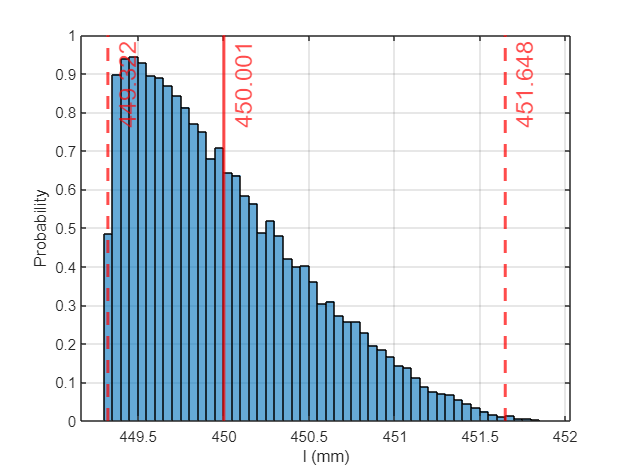

% plot the histogram of the length distribution

histogram(l, "Normalization","pdf")
cl = quantile(l, [alpha/2, 1-alpha/2]); 
xline(mean(l), '-', mean(l), "Color", "r", "LineWidth", 2, "FontSize", 16)
xline(cl(1), '--', cl(1), "Color", "r", "LineWidth", 2, "FontSize", 16)
xline(cl(2), '--', cl(2), "Color", "r", "LineWidth", 2, "FontSize", 16)
xlabel("l (mm)");
ylabel("Probability");
grid

V=pi*r.^2.*l; % calculate the volume

We can now built the histogram of the volume

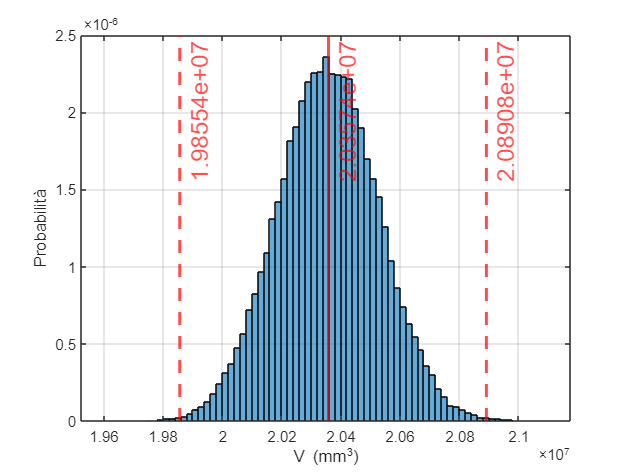

cl = quantile(V, [alpha/2, 1-alpha/2]);
histogram(V, "Normalization","pdf")
xline(mean(V), '-', mean(V), "Color", "r", "LineWidth", 2, "FontSize", 16)
xline(cl(1), '--', cl(1), "Color", "r", "LineWidth", 2, "FontSize", 16)
xline(cl(2), '--', cl(2), "Color", "r", "LineWidth", 2, "FontSize", 16)
xlabel("V (mm^3)");
ylabel("Probabilità");
grid

Now we can calculate the parameter

stdV = std(V)

stdV = 1.7034e+05

I can calculate the stdV using the "*Law of Uncertainty Propagation*"


$$u_V=\sqrt{\left(\frac{\partial V}{\partial r}\right)^2u_r^2 + \left(\frac{\partial V}{\partial l}\right)^2u_l^2 }=
\pi \bar r \sqrt{4\bar l^2 u_r^2+\bar r^2 u_l^2}$$


stdVF = pi * rbar * sqrt( 4 * lbar^2 * ur^2 + rbar^2 * ul^2)

stdVF = 1.7115e+05

The resulting histogram represents the expected distribution for the volume.

It allows to estimate the expected value, the combined standard uncertainty and also allows you to define the prediction and confidence intervals (using the quantile formula)

cl(2) - cl(1)

ans = 1.0354e+06

#### Example 3 (power of a resistor)

You have a purely resisitve circuit that has an equivalent resistence of $R = 4889$ and absorbs a current of $I = 2.9$. The design tolerances are, respectively $t_R = 51$ and $t_I = 0.07$.

Calculate the resulting tolerance on the absorbed power P.


$$u_P=\sqrt{\left(\frac{\partial P}{\partial R}\right)^2u_R^2 + \left(\frac{\partial P}{\partial I}\right)^2u_I^2 }=I \sqrt{I^2 u_R^2+4R^2 u_I^2}$$


clc;
clear;
close all;

R = 4889; % resistence
uR = 51; % standard deviation
I = 2.9; % current
uI = 0.07; % standard deviation

stdV = I * sqrt(I^2 * uR^2 + 4 * R^2 * uI^2);